clear all
close all
X0=[1.2;0;0;-1.04935751];
t0=0;T=2*6.19216933;
mu=1/82.45;mus=1-mu;
x1=@(t,x) x(2);
x2=@(t,x) 2*x(4)+x(1)-mus*(x(1)+mu)./((x(1)+mu).^2+x(3).^2).^3/2-mu*(x(1)-mus)./((x(1)-mus).^2+x(3).^2).^3/2;
x3=@(t,x) x(4);
x4=@(t,x) -2*x(2)+x(3)-mus*x(3)./((x(1)+mu).^2+x(3).^2).^3/2-mu*x(3)./((x(1)-mus).^2+x(3).^2).^3/2;
opt=odeset("RelTol",1e-5);
F=@(t,x) [x1(t,x);x2(t,x);x3(t,x);x4(t,x)];
[t,u]=ode45(F,[t0 T],X0,opt);

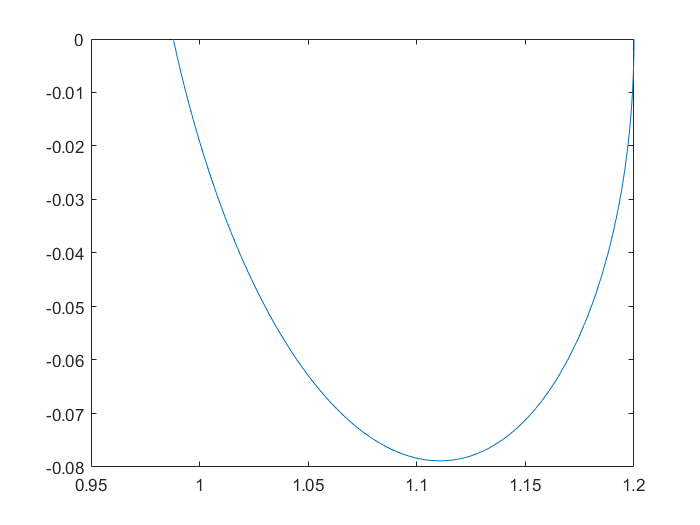

plot(u(:,1),u(:,3))

%[t,u]=ode23s(F,[t0 T],X0,opt)
plot(u(:,1),u(:,3))

clear all
close all
mu=1;
sigma=@(x) sin(x);
f=@(x) (1-cos(x).^2-2*cos(x));
a=0;b=pi;
alpha=0;beta=0;
N=100;
[t,u]=eqlim(f,sigma,mu,a,b,alpha,beta,N)

t = 	1.0e+03 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0161    0.0171    0.0181    0.0191    0.0201    0.0211    0.0221    0.0231    0.0241    0.0251    0.0261    0.0271    0.0281    0.0291    0.0301    0.0311    0.0321    0.0331    0.0341    0.0351    0.0361    0.0371    0.0381    0.0391    0.0401    0.0411    0.0421    0.0431    0.0441    0.0451    0.0461    0.0471    0.0482    0.0492


u =    -1.0690   -0.1254    1.0786    1.5904    0.3005   -3.1058   -3.8448   -1.6990    0.3270    1.3575    0.9089   -2.0416   -3.8656   -2.2457   -0.0780    1.2012    1.2544   -1.1253   -3.8070   -2.8578   -0.5840    0.9606    1.4244   -0.2361   -3.4172   -3.3780   -1.1479    0.6508    1.4417    0.4890   -2.7348   -3.7405   -1.7547    0.2712    1.3407    0.9953   -1.8660   -3.8864   -2.3788   -0.1779    1.1568    1.3026   -0.9349   -3.7532   -2.9737   -0.6950    0.9029    1.4395   -0.0708   -3.2985


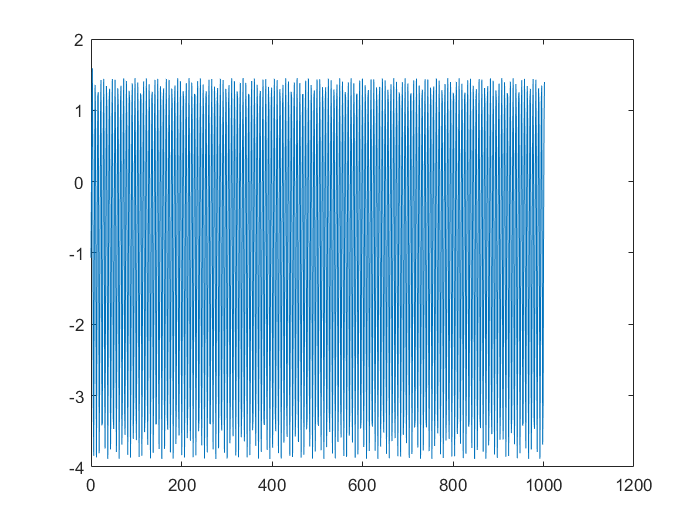

plot(t,u)